# Piston Mechanics

An equation to compute the combustion chamber volume as a function of the crank angle is symbolically analysed. In the end, a Matlab function file is programatically generated. Also, a Simscape Function file is manually made after programatically generating a Simscape equation.

Reference: Section 4.2 Engine Geometry in Eriksson and Nielsen (978-1-118-47999-5, Wiley 2014), referred as [EN14] below.

% load some engine specs
params_cylinder

## Piston Position

Distance between crank axis and piston pin axis.

syms  s(theta)  a  l
eq_pistonpos = s(theta) == a*cos(theta) + sqrt(l^2 - a^2*sin(theta)^2);
disp(eq_pistonpos)

$$s\left(\theta \right)=a\,\cos\left(\theta \right)+\sqrt{l^{2}-a^{2}\,{\sin\left(\theta \right)}^{2}}$$

s_eq = subs(eq_pistonpos, [a l], [params.cylinder.a_mm params.cylinder.l_mm]);
disp(s_eq)

$$s\left(\theta \right)=43\,\cos\left(\theta \right)+\sqrt{\frac{1671849}{100}-1849\,{\sin\left(\theta \right)}^{2}}$$

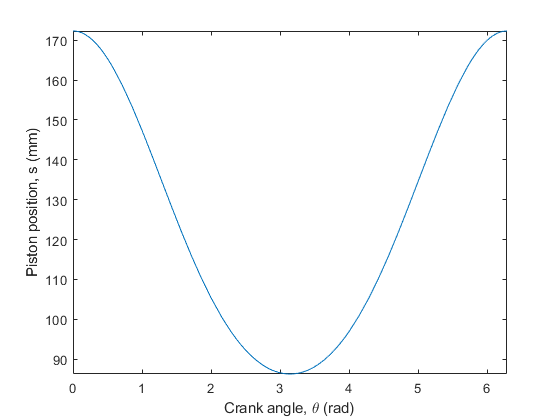

fplot(rhs(s_eq), [0 2*pi])
ylabel('Piston position, s (mm)')
xlabel('Crank angle, \theta (rad)')

## Clearance Volume

syms  r_c  % compression ratio [-]
syms  V_d  % displaced or swept volume [mm^3]
syms  V_c  % clearance volume [mm^3]
assume(V_d > 0)  % suppress warning
eq_compratio = r_c == (V_d + V_c)/V_c;
disp(eq_compratio)

$$r_{c}=\frac{V_{c}+V_{d}}{V_{c}}$$

sol = V_c == solve(eq_compratio, V_c);
disp(sol)  % ==> use RHS of this in "model_parameters.m".

$$V_{c}=\frac{V_{d}}{r_{c}-1}$$

s_eq = subs(sol, [V_d r_c], [params.cylinder.V_d_mm3 params.cylinder.r_c]);
disp(double(rhs(s_eq)))  % clearance volume [mm^3]

   4.3440e+04



## Cylinder Volume

syms  V(theta)  % cylinder volume [mm^3]
syms  B  % bore [mm]
eq_cylvol = V(theta) == V_c + pi*B^2/4*(l + a - s(theta));
disp(eq_cylvol)

$$V\left(\theta \right)=\frac{\pi \,\left(a+l-s\left(\theta \right)\right)\,B^{2}}{4}+V_{c}$$

Vcyl_eq = subs(eq_cylvol, s(theta), rhs(eq_pistonpos));
disp(Vcyl_eq)  % ==> Use RHS of this during simulation.

$$V\left(\theta \right)=\frac{\pi \,\left(a+l-a\,\cos\left(\theta \right)-\sqrt{l^{2}-a^{2}\,{\sin\left(\theta \right)}^{2}}\right)\,B^{2}}{4}+V_{c}$$

% Generate a Matlab Function file
matlabFunction( rhs(Vcyl_eq), ...
    'File', 'cylinder_volume_mm3_matlab', ...
    'Optimize', false, ...
    'Vars', [theta, V_c, a, l, B], ...  % can't chage symbol names
    'Outputs', {'Vcyl_mm3'} );

% Generate a Simscape equation
syms  Vcyl
Vcyl_sscfcndef = simscapeEquation( Vcyl, rhs(Vcyl_eq) ) % can't change symbol names

Vcyl_sscfcndef = 'Vcyl == V_c+B^2*pi*(a+l-a*cos(theta)-sqrt(-a^2*sin(theta)^2+l^2))*(1.0/4.0);'

% dV/dt is also necessary for simulation.
% Here, dV/dtheta is computed.
% Note that dV/dt = dV/dtheta * dtheta/dt = dV/dtheta * w
% where w is the engine speed (rad/s)
dVdtheta_eq = diff(Vcyl_eq, theta);
disp(dVdtheta_eq)  % ==> Use RHS of this during simulation.

$$\frac{\partial }{\partial \theta }V\left(\theta \right)=\frac{\pi \,B^{2}\,\left(a\,\sin\left(\theta \right)+\frac{a^{2}\,\cos\left(\theta \right)\,\sin\left(\theta \right)}{\sqrt{l^{2}-a^{2}\,{\sin\left(\theta \right)}^{2}}}\right)}{4}$$

% dVdtheta is used in only one place in Simscape component source.
syms  dVdt  w
dVdtheta_sscfcndef = simscapeEquation( dVdt, rhs(dVdtheta_eq)*w )

dVdtheta_sscfcndef = 'dVdt == B^2*w*pi*(a*sin(theta)+a^2*cos(theta)*sin(theta)*1.0/sqrt(-a^2*sin(theta)^2+l^2))*(1.0/4.0);'

## Plot for Visual Check

% Visually check that the equation is producing reasonable result:
Vcyl_eq = subs(Vcyl_eq, {a, l, B, V_c}, [params.cylinder.a_mm params.cylinder.l_mm params.cylinder.B_mm params.cylinder.V_c_mm3]);
disp(Vcyl_eq)

$$V\left(\theta \right)=\frac{1492578711336949}{34359738368}-1849\,\pi \,\left(43\,\cos\left(\theta \right)+\sqrt{\frac{1671849}{100}-1849\,{\sin\left(\theta \right)}^{2}}-\frac{1723}{10}\right)$$

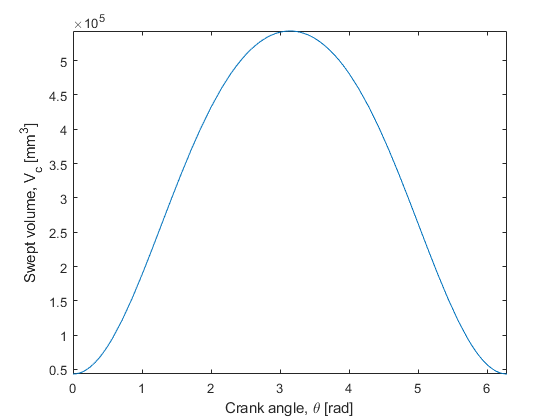

fplot(rhs(Vcyl_eq), [0 2*pi])
ylabel('Swept volume, V_c [mm^3]')
xlabel('Crank angle, \theta [rad]')

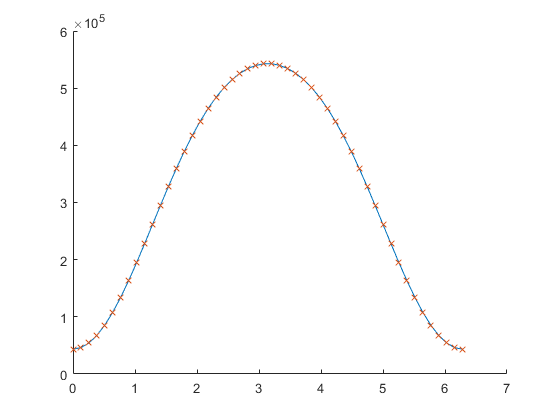

% Check that the numeric version is working okay
% by visually comparing it with the symbolic version.
x = linspace(0, 2*pi, 50);
Vx_sym = double(subs(rhs(Vcyl_eq), theta, x));
Vx_num = cylinder_volume_mm3_matlab(x, params.cylinder.V_c_mm3, params.cylinder.a_mm, params.cylinder.l_mm, params.cylinder.B_mm);
% It would be very useful if Simscape Function is callable from Matlab!
% If that is possible, I would use it here to plot for comparison.
figure
hold on
plot(x, Vx_sym, '-')
plot(x, Vx_num, 'x')